# Molico (2006) Replication

## Calibration

clear all
close all
clc



mupper=700 %highest value if money holdings on the grid

mupper = 700

N=10000 %number of agents for simulating distribution

N = 10000

iterations=5 %maximum number of iterations for the value function iteration    

iterations = 5

stopping_parameter=0 %the smaller, the more does it iteration take to converge

stopping_parameter = 0

x=0.1

x = 0.1000

alpha=1

alpha = 1

theta=1

theta = 1

beta=0.99 %discount factor

beta = 0.9900

M=100 %Money supply

M = 100

r=1/beta-1 %real interest rate

r = 0.0101

## Define grid

% sets up a grid where points are located around 50-100 since under the
% most used calibration, many agents were holding money holdings in that
% range
% grids_1=5
% 
% grids_2=7
% grids_3=5
% grids=grids_1+grids_2+grids_3
% 
% m_0=linspace(0,80,grids_1)
% m_1=linspace(90,200, grids_2)
%  m_2=linspace(220,mupper,grids_3);
%  m=[m_0,m_1,m_2]
grids=30

grids = 30

m=linspace(0,mupper, grids)

m =          0   24.1379   48.2759   72.4138   96.5517  120.6897  144.8276  168.9655  193.1034  217.2414  241.3793  265.5172  289.6552  313.7931  337.9310  362.0690  386.2069  410.3448  434.4828  458.6207  482.7586  506.8966  531.0345  555.1724  579.3103  603.4483  627.5862  651.7241  675.8621  700.0000


## Options



test_interpolation=0; % checks the interpolation method and displays the initial guess of the value function
test_utility=0; % displays the utility and cost function
display_plot_V=1;
display_plot_q=1;
display_plot_d=1;
display_plot_meeting=0;
display_plot_Distribution_rough=0;
display_plot_Distribution_smooth=0;
display_plot_cdf=0;
display_plot_money_savings=1;
display_plot_M_Track_1=1;






## set up matrixes

initial_distribution_shock=ones(1,N);
Distribution_number=ones(1,N);
Distribution_0=ones(1,N);
cdf_0=zeros(1,grids);
lamdba_0=zeros(1,grids);
m_savings_1=zeros(1,grids)

m_savings_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m_savings_2=zeros(1,grids)

m_savings_2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m_savings_3=zeros(1,grids)

m_savings_3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


## Initial Guess

% set an initial guess for the value function
V0=log(1+m)*100  ;

 
% set an initial guess for the pdf distributiuon

for j=1:grids
if m(1,j)>M
lamdba_0(1,j)=1;
break
end
end



M=lamdba_0*m';

%ISSUE: the guess was choosen such that that the implied money supply is
%equal to M. But then the pdf does not sum to 1. I don't think this is a
%problem since after 


% compute cdf
for i=1:grids-1
    cdf_0(1,1)=lamdba_0(1,1);
cdf_0(1,i+1)=cdf_0(1,i)+lamdba_0(1,1+i);
end


% Draw from the initial guess
% we draw a random shock [0,1] for each individual in N. Depending on the
% initial guess, the cdf will determine the distributiuon. Notice, the
% distribution_number is determined to determine the grid point which can
% then be used to determine the money holding by using the grid m

found=0; %this parameter indicates whether a certain condition in the loop was satisfied
for i=1:N
initial_distribution_shock(1,i)=unifrnd(0,1); 
for l=1:grids 
   if initial_distribution_shock(1,i)<cdf_0(1,l)
Distribution_number(1,i)=l;
Distribution_0(1,i)=m(1,Distribution_number(1,i));
found=1;
   end
    
if found==1
found=0;
    break
end
       
end

end

 


## Test interpolation: spline, extrapolate


if test_interpolation==1
    n_interp=1000
V_interp=ones(n_interp);
m_interp=linspace(1,mupper,n_interp);
for i=1:n_interp
V_interp=interp1(m,V0,m_interp,'spline',"extrap");
end

%Plot
hold on

plot(m,V0)
plot(m_interp,V_interp)
legend('grids', 'interpolation')

hold off

clear  m_interp n_interp V_interp
end


## Test utility and cost function


if test_utility==1
u=Utility(m)
c=cost_function(m)
s=u-c
figure(1)

hold on
plot(m, u)
plot(m,c)
plot(m,s)
legend('Utility', 'Cost', 'Surplus')
title('Functional Form')
hold off
clear u c s
end

## Iteration

 [V,q,d,Distribution,lamdba,cdf,M_track_1, M_track_2,Meeting] = Iter_Molico_06(iterations, N,m...
     ,grids,V0,lamdba_0, cdf_0,Distribution_0,r,alpha,x,mupper, stopping_parameter,0)

V =          0  322.4378  389.7434  429.6112  458.0383  480.1474  498.2425  513.5596  526.8391  538.5602  549.0504  558.5439  567.2138  575.1916  582.5797  589.4593  595.8959  601.9432  607.6455  613.0402  618.1586  623.0278  627.6708  632.1078  636.3563  640.4316  644.3473  648.1155  651.7468  655.2508


lamdba =      0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


cdf =      0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.0460         0         0         0         0


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.0460    1.0497         0         0         0


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.0460    1.0497    1.0529         0         0


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.0460    1.0497    1.0529    1.0562         0


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.0460    1.0497    1.0529    1.0562    1.0596


Value function has not converged


i = 5

V =     0.0000  364.9650  436.8060  467.2347  492.5352  511.2133  526.4975  539.3685  550.4626  560.2222  568.9267  576.7825  583.9391  590.5102  596.5840  602.2300  607.5042  612.4523  617.1121  621.5153  625.6883  629.6541  633.4321  637.0392  640.4902  643.7979  646.9737  650.0277  652.9689  655.8051


q =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.9255    0.8549    0.6668    0.6702    0.6165    0.5711    0.5365    0.5024    0.4724    0.4448    0.4193    0.3957    0.3737    0.3530    0.3336    0.3153    0.2980    0.2815    0.2660    0.2511    0.2370    0.2235    0.2106    0.1982    0.1864    0.1750    0.1641    0.1536    0.1435    0.0000
    0.9697    0.9381    0.8597    0.8553    0.8272    0.8042    0.7845    0.7651    0.7474    0.7307    0.7149    0.6998    0.6855    0.6719    0.6588    0.6462    0.6341    0.6225    0.6113    0.6005    0.5900    0.5799    0.5701    0.5606    0.5513    0.5424    0.5337    0.5252    0.5170    0.0000
    0.9682    0.9355    0.8609    0.8558    0.8308    0.8113    0.7946    0.7787    0.7643   

d =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4936    0.8773    1.7286    1.6771    1.8318    1.9475    2.0114    2.0633    2.0956    2.1145    2.1222    2.1205    2.1109    2.0944    2.0720    2.0444    2.0123    1.9761    1.9363    1.8933    1.8473    1.7987    1.7477    1.6946    1.6394    1.5825    1.5238    1.4637    1.4021         0
    1.2904    2.3858    5.1455    4.9862    5.5904    6.0933    6.4276    6.7493    7.0140    7.2455    7.4494    7.6293    7.7899    7.9337    8.0631    8.1799    8.2856    8.3815    8.4687    8.5480    8.6203    8.6862    8.7463    8.8011    8.8510    8.8965    8.9378    8.9753    9.0093         0
    1.2272    2.2731    5.1943    5.0067    5.7376    6.3865    6.8426    7.3026    7.6989   

Distribution =     1.0070    1.4947    0.5375    0.9832    0.9957    0.9819    1.4725    0.5275    1.0000    1.5250    0.4750    1.0181    0.9819    1.0232    0.9768    1.0000    1.4725    1.0539    0.4807    0.9930    1.0070    0.9930    1.5320    0.4680    1.0000    1.0000    1.0392    0.9608    1.0000    1.0000    1.0000    1.0000    1.5183    2.0365         0    1.0000    1.0000    1.4933    0.5067    1.0232    1.9569    0.0200    1.0392    1.4796    0.4812    1.0000    1.0128    0.9872    1.0000    1.0000


lamdba =     0.0678    0.9322         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


cdf =     0.0678    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


M_track_1 =    22.1345   22.2962   22.3614   22.4097   22.5014


M_track_2 = 1.0e+04 *

    1.0460    1.0497    1.0529    1.0562    1.0596


Meeting =      2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     1     2     2     2     2



 if cdf(grids)==1
    disp('cdf adds up to one')
else 
    disp('cdf does not add up to one')
    cdf(grids)
end

cdf adds up to one


## Plots

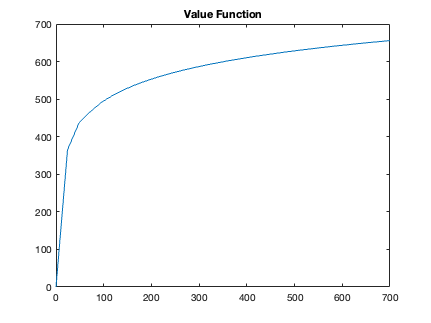

%Plot V
 if display_plot_V==1
figure(1)
plot(m,V)
title('Value Function')

 end

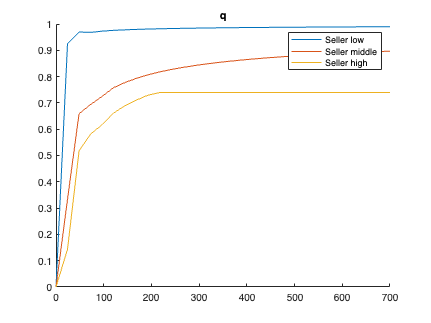



%Plot Distribution Smooth
if display_plot_Distribution_smooth==1 
    for i=1:N
    if Distribution(1,i)==0;
        Distribution(1,i)=0.001;
    end
    end

[f,xi] = ksdensity(Distribution,'Support','positive','BoundaryCorrection','reflection','Bandwidth',std(Distribution)*0.1); 

figure(2)
plot(xi,f)
 end



%Plot Distribution Rough
if display_plot_Distribution_rough==1
figure(3)
histogram(Distribution,grids*2)
 title('Distribution of Money holdings')
 end




%Plot q
 if display_plot_q==1
figure(4)
hold on
plot(m,q(:,1))
plot(m,q(:,round(grids/2)))
plot(m,q(:,grids-1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('q')
 end

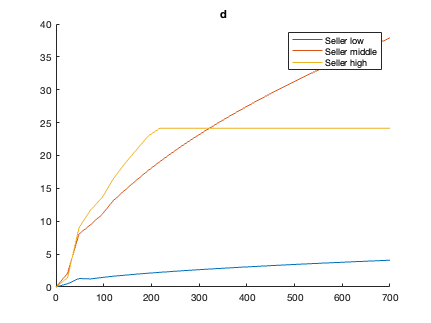





%Plot d
 if display_plot_d==1
figure(5)
hold on
plot(m,d(:,1))
plot(m,d(:,round(grids/2)))
plot(m,d(:,grids-1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('d')
 end

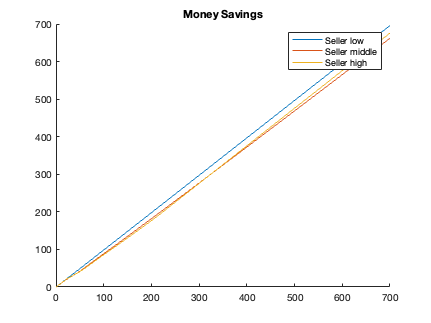


%Plot cdf
if display_plot_cdf==1
figure (6)
plot(m,cdf)
title('cdf')
end


% Plot Money Savings
if display_plot_money_savings==1
m_savings_1=m'-d(:,1);
m_savings_2=m'-d(:,round(grids/2));
m_savings_3=m'-d(:,grids-1);
figure(7)
hold on
plot(m',m_savings_1)
plot(m',m_savings_2)
plot(m',m_savings_3)
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('Money Savings')
end

index =      1     2     3     4     5


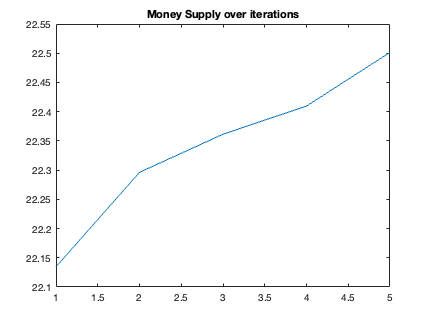




% Plot Mettings
if display_plot_meeting==1
for i=1:N
Meeting(1,i)=m(1,Meeting(1,i));
end
figure (8)
histogram(Meeting,grids)
title('Meetings of agents')
end



%Plot M_track_1
if display_plot_M_Track_1==1
index=[1:iterations]
figure(9)
plot(index, M_track_1)
title('Money Supply over iterations')
end




average_q=sum(sum((lamdba'*lamdba)*q'))

average_q = 27.9062

mean(d./q)

ans =     2.7025    5.1071   12.4555   12.3001   14.5222   16.4059   17.9230   19.4356   20.8032   22.1009   23.3279   24.4964   25.6146   26.6884   27.7229   28.7224   29.6903   30.6295   31.5427   32.4319   33.2991   34.1459   34.9738   35.7841   36.5780   37.3564   38.1204   38.7373   28.9372         0
